clear all
close all
addpath(genpath('/data/drive/postdoc/talks/labmeeting_Bayes_march2020/models/dev'));
addpath(genpath('~/tools/matlab/shared_functions'))
iter = 10;
domain = 0; % 0 = positive domain; -1 = negative domain   
ncues = 3;
noparams = 3;
clear('out', 'C')
params = {'alpha', 'beta', 's0'};
noruns = 3;

D = [];
for nr = 1:noruns
    limits= [0 10; 0 1; 0 1];
    t = 1;
    for al = 0:2:10
        for be = 0:0.2:1
            for s0 = 0:0.2:1 
                D.true(nr, t,1) = al;
                D.true(nr, t,2) = be;
                D.true(nr, t,3) = s0;
                % Generate distributions of rewards
                n = 120;
                % data
                d=[];
                d.cookies_morning = 30+7*randn(1,n);
                d.ch_present      = binornd(zeros(1,n)+1, 0.5);
                d.h               = 8;
                
                % use current parameter combination to generate time series
                o = m2(D.true(nr, t, :), d)
                d.cookies_evening = o.c_ev;
                
                % fit model
                
                for i = 1:noparams %SPECIFIED to 3 params
                    while true
                        initial_val(i) = rand * limits(i,2);
                        if initial_val(i) > limits(i,1) && initial_val(i) < limits(i,2)
                            break
                        end
                    end
                end
                
                lb = limits(:,1)';
                ub = limits(:,2)';
                
                
                X0(1:noparams) = initial_val;
     
                [X, err] = bads(@m2_error, X0, lb, ub, [], [], [], [], d);
                D.err(nr) = err;
                D.est(nr, t,:) = X;
               
             t = t+1;
            end
        end
    end
end

save(['m2_' num2str(noruns) 'runs.mat']);

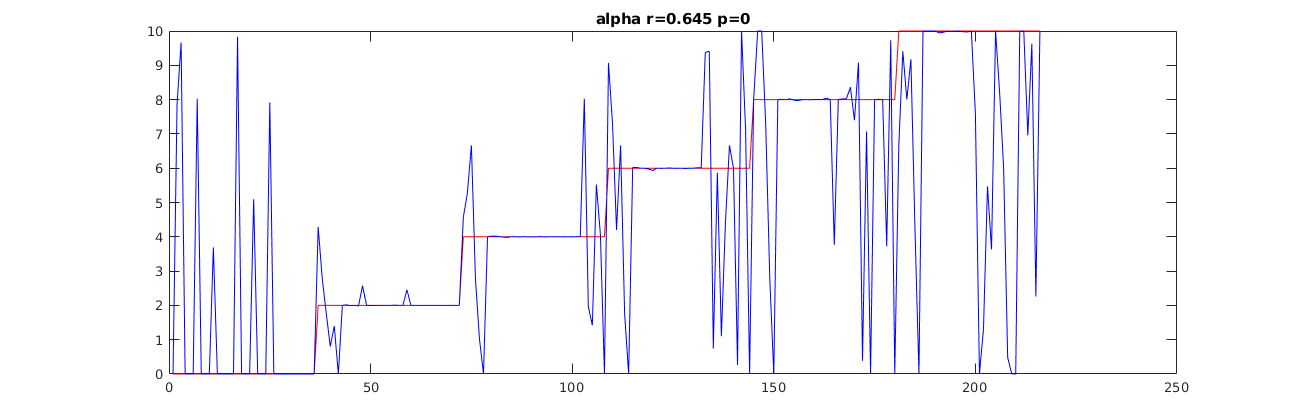

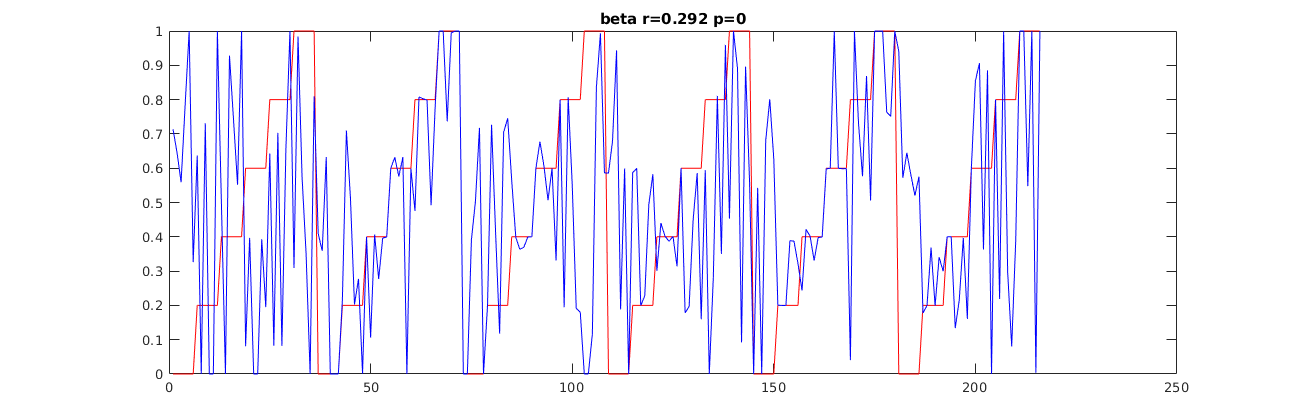

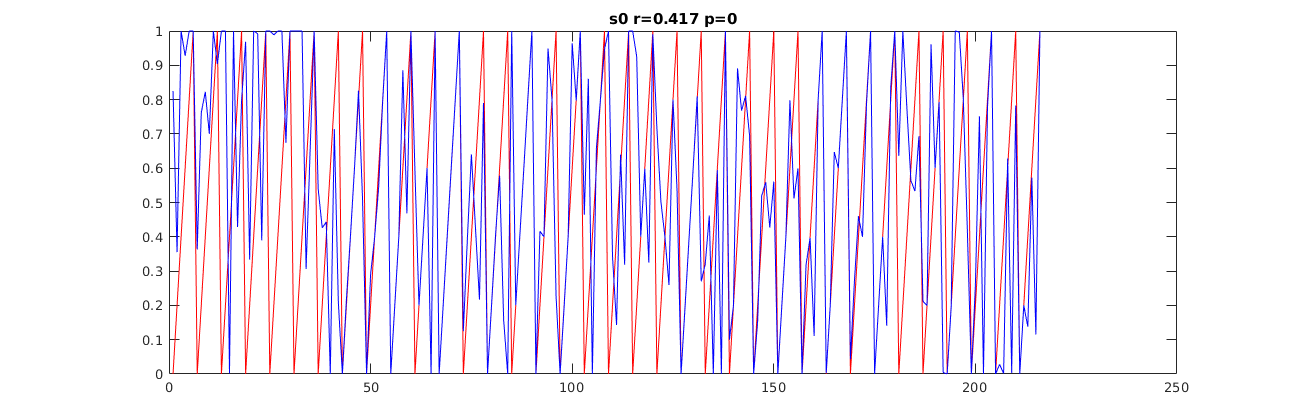

load(['m2_' num2str(noruns) 'runs.mat']);
minerr  = find(D.err==min(D.err));
for np = 1:noparams
    A = [squeeze(D.true(minerr,:,np))' squeeze(D.est(minerr,:,np))'];
    [rr, pp] = corr(A(:,1), A(:,2));    
    f=figure;
    plot(A(:,1), 'Color', 'r');
    hold on 
    plot(A(:,2), 'Color', 'b');
    %legend({'true', 'estimated'});
    title([params{np} ' r=' num2str(round(rr,3)), ' p=' num2str(round(pp,3))]);
    f.Position(3) = 1300;
end

load(['m2_' num2str(noruns) 'runs.mat']);
minerr  = find(D.err==min(D.err));
minerr = minerr(1)
A = [squeeze(D.est(minerr,:,:))];
[R,P] = corrcoef(A)
f=figure;
clf
heatmap(array2table(R, 'VariableNames', {'alpha', 'beta', 's0'}), params, params)